clear all;
close all;

%% load essentials

% addpath(genpath("Models"));                     % load all models
addpath(fullfile("Models","TemplateMatching")); % load TemplateMatching
addpath(fullfile("Models","VGGFace"));          % load VGGFace
addpath("Common");                              % load common functions

paramsPath = fullfile("Weights","VGGFace","params.mat");
myFacePath = fullfile("FaceDatabase","myFace");

% Constants
targetSize = [224 224 3];       % target size for the network

% load images
imds = imageDatastore(myFacePath);    % prepare test images (not loaded yet)

% load model
myModel = VGGFace(paramsPath);        % load model along with pretrained model weights

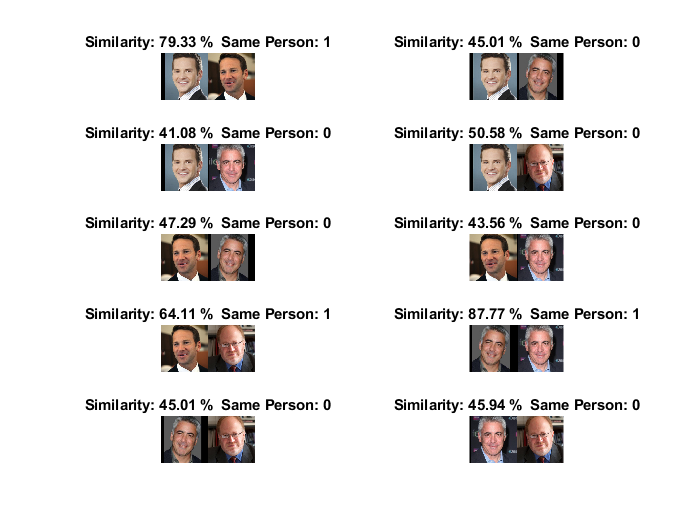

count = 1;
img1 = zeros([targetSize 1], "single");
img2 = zeros([targetSize 1], "single");
num_images = factorial(length(imds.Files)) / (2 * factorial(length(imds.Files) - 2));
for i = 1:length(imds.Files)
    for k = i+1 : length(imds.Files)
        img1(:,:,:,1) = imresize(readimage(imds, i), targetSize(1:2));
        img2(:,:,:,1) = imresize(readimage(imds, k), targetSize(1:2));
        img1n = dlarray(normalizeBatch(img1),"SSCB");
        img2n = dlarray(normalizeBatch(img2),"SSCB");
        result = verifyBatch(myModel, img1n, img2n, [0 0], "cosine");
        subplot(ceil(double(num_images)/2),2,count);
        imshowpair(img1(:,:,:,1)/255, img2(:,:,:,1)/255, "montage");
        title(sprintf("Similarity: %.2f %%  Same Person: %d", (1-result.distance)*100, result.boolean));
        count = count + 1;
        drawnow
    end
end